# Evaluation of the models

We have just finished training a model, applied filters to improve its detections, and observed that it is capable of correctly detecting apples, oranges, and pears. However, we still do not know how well the model truly performs.

In this lesson, we will learn how to evaluate object detection models. We will explore the meaning of each evaluation metric and what it reveals about the model’s performance. This understanding will help us assess the true quality of our model. Furthermore, it will allow us to compare multiple models to **identify the best one**, guiding us in** selecting the most appropriate parameters for training future models.**

When training models, as we did in the previous lesson, a folder is automatically created for each run at the path: `runs/detection/created_folder`, typically named "`train" `followed by an identifier, unless a custom name was specified in the configuration.

This folder contains all the plots and graphs that we will discuss in this lesson, along with a `results.csv` file that stores the evaluation metrics. Inside this directory, there is also a subfolder named `weights` where the model weights are saved.

Please note that the graphs shown in this lesson may differ slightly from the ones in the training folder, as they are simplified versions intended to help you understand the concepts more clearly.

**Add Help Module Path**

First, we add the help module:

addpath('help-module');

## Loading a model 

With this code, we are loading the model trained in the previous lesson.

datasetFolder = "datasets/fruits_3_4998/";    
modelPath = fullfile(pwd, 'runs', 'detect', 'train', 'weights');
configFile  = datasetFolder + "data.yaml";

disp("Loading Model....");

Loading Model....


model = utils.loadModel(modelPath, configFile);
disp("Model loaded!");

Model loaded!


## Predicting on the validation dataset

In machine learning, it is not enough for a model to perform well on the data it has seen during training. If we evaluate the model using that same data, we risk overestimating its true performance. This happens because the model might have "memorized" the answers instead of actually learning to generalize.

To determine whether a model has truly learned, we need to test it on **new data that it has not seen before.** This is known as the **validation set**. Evaluating the model on this unseen data gives us a much more realistic idea of how it will behave in real-world situations.

In the following code, we use the validation data from our dataset to obtain the model’s predictions on that set. In the next sections, we will use these predictions to calculate the model’s performance metrics.

splitFolder = datasetFolder + "val";
classNames =  utils.ReadClassNames(configFile);
disp("Calculating predictions...")

Calculating predictions...


predictions = utils.getPredictions(model, splitFolder, classNames);
disp("Done!")

Done!


## **calculateIoU**

In this section, we incorporate the calculateIoU function that we implemented in the previous Post-processing lesson.

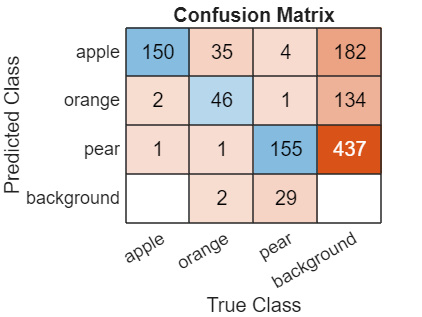

function iou = calculateIoU(b1, b2)
    % Calculates the Intersection over Union (IoU) between two bounding boxes.
    %
    % Inputs:
    %   b1 - 1x4 vector representing the first bounding box [x1 y1 x2 y2]
    %   b2 - 1x4 vector representing the second bounding box [x1 y1 x2 y2]
    %
    % Output:

    %   iou - Scalar value between 0 and 1 representing the IoU.
    %         IoU = 0 if there is no overlap.
    %         IoU = 1 if boxes are identical.
    x1 = max(b1(1), b2(1));
    y1 = max(b1(2), b2(2));
    x2 = min(b1(3), b2(3));
    y2 = min(b1(4), b2(4));
    inter = max(0, x2-x1) * max(0, y2-y1);
    area1 = (b1(3)-b1(1))*(b1(4)-b1(2));
    area2 = (b2(3)-b2(1))*(b2(4)-b2(2));
    union = area1 + area2 - inter;
    if union>0
        iou = inter/union;
    else
        iou = 0;
    end
end

## Confusion matrix

A **confusion matrix** summarizes how often the model correctly or incorrectly predicts each class for the detected objects.

Each **row** represents the actual class, and each **column** represents the predicted class.

The **diagonal** contains the correct predictions (predicted class = actual class).

Values **outside the diagonal** indicate class confusions (e.g., it predicted "apple" when it was actually "pear").

To construct the matrix, only detections with sufficient confidence and IoU are considered:

- **True Positive (TP):** confidence > threshold and IoU > threshold.

- **False Positive (FP):** confidence > threshold and IoU < threshold.

- **False/True Negative (FN/TN):** confidence < threshold, meaning the model did not detect the object.

The matrix helps identify which classes are most often confused and assess **per-class performance**.

It is useful for analyzing class-level errors and evaluating the model’s performance by class.

The following code calculates the confusion matrix for the model using the function you have created before:

classNames =  utils.ReadClassNames(configFile);
confidenceThreshold = 0.25;

confMat = utils.computeConfusionMatrix(predictions, classNames, confidenceThreshold, @calculateIoU);

The following code displays the confusion matrix:

allClassNames = [classNames(:); {'background'}];
utils.displayConfusionMatrix(confMat, allClassNames);

### Exercise 2 -  Extract TP, FP, FN of each class

Implement a function that extracts the true positive, false positive, and false negative values for each class.

function [TP, FP, FN] = extractConfusionMatrixValues(confusionMat)

     ClassName      True Positive
    ____________    _____________

    "apple"              150     
    "orange"              46     
    "pear"               155     
    "background"           0     



    % Extracts True Positive, False Positive, and False Negative values for each class

     ClassName      False Positive
    ____________    ______________

    "apple"              221      
    "orange"             137      
    "pear"               439      
    "background"          31      



    %

     ClassName      False Negative
    ____________    ______________

    "apple"                3      
    "orange"              38      
    "pear"                34      
    "background"         753      



    % Input:
    %   confusionMat - Square confusion matrix where rows represent actual classes
    %                  and columns represent predicted classes.
    %
    % Outputs:
    %   TP - Vector of true positives per class (correct predictions)
    %   FP - Vector of false positives per class (incorrect predictions assigned to the class)
    %   FN - Vector of false negatives per class (missed detections of the class)

    numClasses = size(confusionMat, 1);
    TP = zeros(numClasses, 1);
    FP = zeros(numClasses, 1);
    FN = zeros(numClasses, 1);
    for i = 1:numClasses
        TP(i) = confusionMat(i, i);
        FP(i) = sum(confusionMat(i, :)) - TP(i);
        FN(i) = sum(confusionMat(:, i)) - TP(i);
    end
end


The following code generates tables of true positives, false positives, and false negatives to visualize the values extracted for each class.

[TP, FP, FN] = extractConfusionMatrixValues(confMat);

tableTP = table(string(allClassNames), TP, 'VariableNames', {'ClassName', 'True Positive'});
tableFP = table(string(allClassNames), FP, 'VariableNames', {'ClassName', 'False Positive'});
tableFN = table(string(allClassNames), FN, 'VariableNames', {'ClassName', 'False Negative'});

    ClassName    Precision
    _________    _________

    "apple"        0.4698 
    "orange"      0.24444 
    "pear"        0.23604 
    "Overall"     0.31676 




disp(tableTP)
disp(tableFP)
disp(tableFN)

## **Precision**

**Precision** measures the **accuracy of the model for a given class**. It is defined as the **proportion of true positives (TP)** relative to the **total number of predicted positives (TP + FP)**.

Mathematically:  $\textrm{Precision}=\frac{\textrm{TP}}{\textrm{TP}+\textrm{FP}}$

There are different ways to compute precision:

- **Per-class precision**: One value for each class.

- **Global precision**: Overall precision across all classes.

- **Balanced (macro-averaged) precision**: Average of per-class precision (excluding background).

The **range** of precision is from **0 to 1**:

- **Precision = 1** means **every positive prediction was correct.**

- **Precision = 0** means **none of the positive predictions were correct**.

### Exercise 3 -  Calculate the precision of the model

In this exercise, you must implement a MATLAB function to compute the **precision for each class **and **overall precision** (macro-averaged precision).

**Remember** 

- (/) is matrix division. 

- (./) is element-wise division

**Solution**

function precision = precisionFunc(predictions, classNames, confidenceThreshold, calculateIoU)   
 % Computes per-class and macro-averaged precision from predictions.
    % Output:
    %   precision            - Row vector of precision values:
    %                          * One value per class (same order as classNames).

    ClassName    Recall 
    _________    _______

    "apple"      0.91503
    "orange"     0.52381
    "pear"       0.69312
    "Overall"    0.71065



    %                          * One additional final value representing the macro-averaged
    %                            precision (mean of per-class precisions, excluding background).
    confMat = utils.computeConfusionMatrix(predictions, classNames, confidenceThreshold, calculateIoU);
    [TP, FP, FN] = extractConfusionMatrixValues(confMat);

    denom = (TP + FP);

    precision = TP ./ denom;
    totalTP = sum(TP);
    total = totalTP + sum(FP);
    

    ClassName    Precision    Recall 
    _________    _________    _______

    "apple"        0.4698     0.91503
    "orange"      0.24444     0.52381
    "pear"        0.23604     0.69312
    "Overall"     0.31676     0.71065



    if total == 0
        total = NaN;
    end

    precisionWithoutBG = precision(1:end-1);

    % Handle NaNs if any class has 0 TP+FP
    precisionMacro = mean(precisionWithoutBG(~isnan(precisionWithoutBG)));
    precision = [precisionWithoutBG; precisionMacro];
    
end

**Precision Table**

confidenceThreshold = 0.5;
precision = precisionFunc(predictions, classNames, confidenceThreshold, @calculateIoU);
metricsClassNames = string([classNames(:); {'Overall'}]);
precisionTable = table(metricsClassNames, precision, 'VariableNames', {'ClassName', 'Precision'});
disp(precisionTable)

## **Recall**

**Recall** measures the **sensibility of the model for a given class**.  It is defined as the **proportion of true positives (TP)** relative to the **total number of actual positives (TP + FN)**

Mathematically:  $\mathrm{Recall}=\frac{\mathrm{TP}}{\mathrm{TP}+\mathrm{FN}}$

Just like with precision, there are different ways to compute recall:

- **Per-class recall**: One value for each class.

- **Global recall**: Overall recall across all classes.

- **Balanced (macro-averaged) recall**: Average of per-class recall (excluding background).

The **range** of recall is from **0 to 1**:

- **Recall = 1**  means the model **found all** the actual positive samples .

- **Recall = 0** means the model **missed all** the actual positives .

### Exercise 4 -  Calculate the recall of the model

In this exercise, you must implement a MATLAB function to compute the recall** for each class **and **overall recall** (macro-averaged recall).

**Remember** 

- (/) is matrix division. 

- (./) is element-wise division

function recall = recallFunc(predictions, classNames, confidenceThreshold, calculateIoU)
    % Computes per-class and macro-averaged recall from predictions.
    % Output:
    %   recall - Row vector of recall per class, with an additional entry

    ClassName    Precision    Recall     F1-Score
    _________    _________    _______    ________

    "apple"       0.48929     0.89542    0.63279 
    "orange"      0.24852         0.5    0.33202 
    "pear"        0.25097     0.68254      0.367 
    "Overall"     0.32959     0.69265    0.44394 



Computing plot...
     1    21



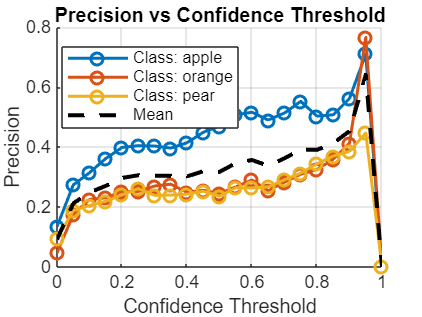

    %            at the end representing the macro-averaged recall.

    confMat = utils.computeConfusionMatrix(predictions, classNames, confidenceThreshold, calculateIoU);
    [TP, FP, FN] = extractConfusionMatrixValues(confMat);

    denom = (TP + FN);
    recall = TP ./ denom;

    totalTP = sum(TP);

Computing plot...
     1    21



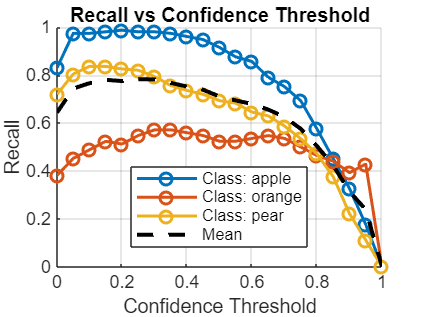

    total = totalTP + sum(FN);

    if total == 0
        total = NaN;
    end

    recallWithoutBG = recall(1:end-1);


    % Handle NaNs if any class has 0 TP+FN
    recallMacro = mean(recallWithoutBG(~isnan(recallWithoutBG)));
    recall = [recallWithoutBG; recallMacro];
end


**Recall Table**

Computing plot...
     1    21



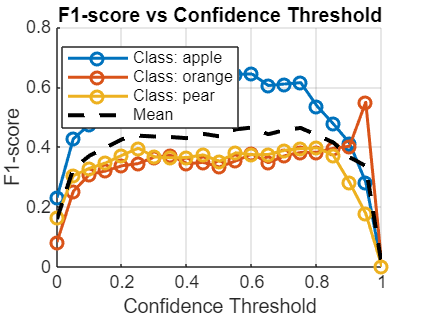

confidenceThreshold = 0.5;

recall = recallFunc(predictions, classNames, confidenceThreshold, @calculateIoU);
metricsClassNames = string([classNames(:); {'Overall'}]);
recallTable = table(metricsClassNames, recall, 'VariableNames', {'ClassName', 'Recall'});
disp(recallTable)

### Exercise 5 -  Precision/Recall

In this exercise, you must change the value of `confidenceThreshold` and answer the following questions.

confidenceThreshold = 0.5;
precision = precisionFunc(predictions, classNames, confidenceThreshold, @calculateIoU);
recall = recallFunc(predictions, classNames, confidenceThreshold, @calculateIoU);
metricsClassNames = string([classNames(:); {'Overall'}]);
metricsTable = table(metricsClassNames, precision(:), recall(:), ...
    'VariableNames', {'ClassName', 'Precision', 'Recall'});

Loading Model....


Model loaded!


disp(metricsTable)

**Question:**

What did you observe when changing the value of `confidenceThreshold`? Why does this happen?

**Answer:**

When changing the value of `confidenceThreshold`, I observed a trade-off between precision and recall. Specifically:

- **Increasing the confidence threshold** led to **higher precision** but **lower recall**. This is because the model becomes more selective, only making predictions when it is more confident. As a result, it reduces false positives but also misses some true positives.

- **Decreasing the confidence threshold** increased **recall** but reduced **precision**, as the model makes more predictions, capturing more true positives but also increasing the number of false positives.

This behavior reflects the typical **precision-recall trade-off**, where improving one metric often leads to a decrease in the other. Finding the right balance depends on the specific requirements of the application.

## F1-Score

As we observed in the previous exercise, there is a trade-off between **precision** and **recall**. To summarize both metrics into a single value, we use the **F1-score**, which balances the two.

The **F1-score** is the harmonic mean of precision and recall, and is defined as:


$${\textrm{f1}}_{\textrm{score}} =\frac{2\cdot \textrm{presicion}\cdot \textrm{recall}}{\textrm{precision}+\textrm{recall}}$$


Just like precision and recall, the F1-score can be computed in several ways:

- **Per-class F1-score**: One value for each class.

- **Global F1-score**: Overall performance across all classes.

- **Balanced (macro-averaged) F1-score**: Average of the per-class F1-scores (excluding background class, if any).

The **range** of the F1-score is from **0 to 1** :

- **F1-score = 1** means perfect precision and recall.

- **F1-score = 0** means either precision or recall is zero, the model fails in some key way.

A good F1-score indicates a good balance between **avoiding false positives** (high precision) and **not missing positives** (high recall).

### Exercise 6 -  Calculate the F1-Score of the model

In this exercise, you must implement a MATLAB function to compute:

- The **F1-score for each class**, and

- The **overall F1-score** using macro-averaging.

To do this, you will **reuse** the `precisionFunc` and `recallFunc` functions you defined earlier.

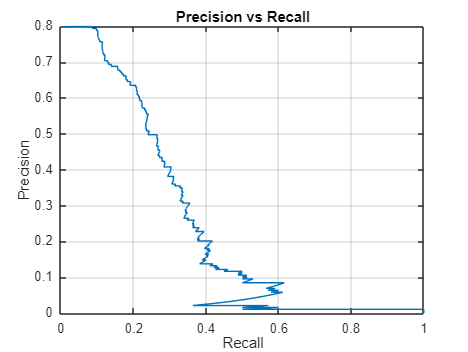

function f1 = f1ScoreFunc(predictions, classNames, confidenceThreshold, calculateIoU)
    % Computes per-class and macro-averaged F1-score using recall and precision.
    % Output:
    %   f1 - Row vector of F1-score per class, with an additional entry
    %        at the end representing the macro-averaged F1-score.

    % Get precision and recall
    recall = recallFunc(predictions, classNames, confidenceThreshold, calculateIoU);
    precision = precisionFunc(predictions, classNames, confidenceThreshold, calculateIoU);

    % Remove macro values (last element)
    recallPerClass = recall(1:end-1);
    precisionPerClass = precision(1:end-1);

    % Compute F1-score per class
    f1PerClass = 2 * (precisionPerClass .* recallPerClass) ./ ...
                 (precisionPerClass + recallPerClass);

    % Handle NaNs where precision + recall = 0
    f1PerClass(isnan(f1PerClass)) = NaN;

    % Macro-averaged F1 (excluding background and NaNs)

    f1Macro = mean(f1PerClass(~isnan(f1PerClass)));

    % Concatenate per-class F1 and macro
    f1 = [f1PerClass; f1Macro];
end

**F1-Score Table**

confidenceThreshold = 0.53;
precision = precisionFunc(predictions, classNames, confidenceThreshold, @calculateIoU);

ap


recall = recallFunc(predictions, classNames, confidenceThreshold, @calculateIoU);

    0.2110
    0.3773
    0.2517



f1 = f1ScoreFunc(predictions, classNames, confidenceThreshold, @calculateIoU);

mAP


    0.2800



metricsClassNames = string([classNames(:); {'Overall'}]);
metricsTable = table(metricsClassNames, precision(:), recall(:), f1(:), ...
    'VariableNames', {'ClassName', 'Precision', 'Recall', 'F1-Score'});
disp(metricsTable)

    NumObjects    mAPOverlapAvg    mAP0.5 
    __________    _____________    _______

       426           0.27999       0.27999



## Curves

In this section, we present the following curves: **precision vs. confidence**,** recall vs. confidence**, and **F1-score vs. confidence**. These plots provide a clearer visualization of the trade-off between precision and recall discussed in Exercise 5, and illustrate how the F1-score balances these two metrics.

### Precision / Confidence curve

The following code generates the **precision vs confidence curve**:

utils.plotMetric('Precision', predictions, classNames, @precisionFunc, @calculateIoU); 

              NumObjects    APOverlapAvg     AP0.5 
              __________    ____________    _______

    apple        153          0.21101       0.21101
    orange        84          0.37729       0.37729
    pear         189          0.25167       0.25167



The image below shows examples of what the **precision vs confidence **curve may look like in **good**, **regular**, and **poor** scenarios.

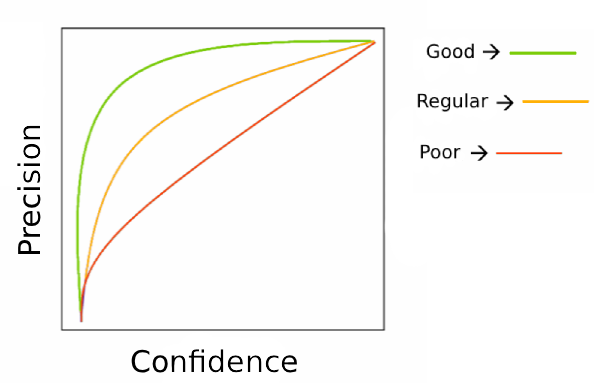

### Recall / Confidence curve

The following code generates the** recall vs confidence curve**:

utils.plotMetric('Recall', predictions, classNames, @recallFunc, @calculateIoU);

The image below shows examples of what the **recall vs confidence** curve may look like in **good**, **regular**, and **poor** scenarios.

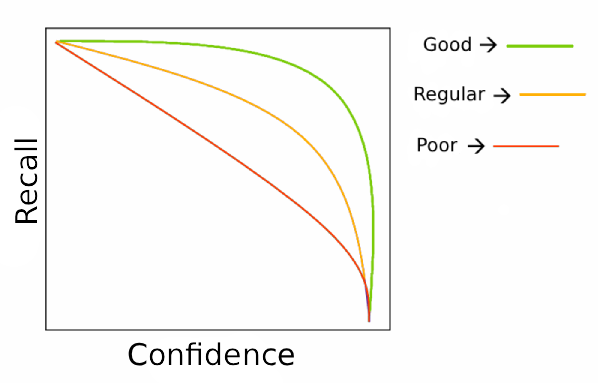

### F1-Score / Confidence curve

The following code generates the** f1-score vs confidence curve:**


utils.plotMetric('F1-score', predictions, classNames, @f1ScoreFunc, @calculateIoU);  

The image below shows examples of what the** f1-score vs confidence** curve may look like in **good**, **regular**, and **poor** scenarios.

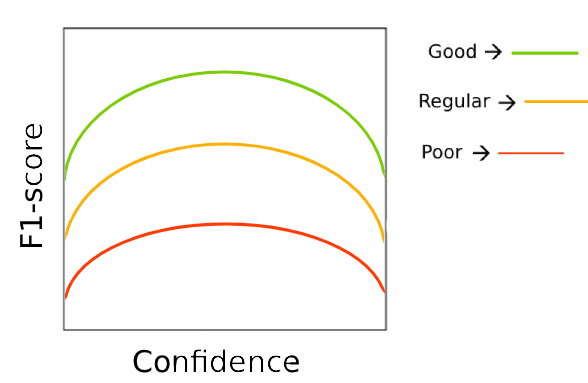

## Precision / Recall curve and Area under Curve

In this section, we'll use MATLAB’s built-in functions to compute and visualize the precision-recall curve.

Although we could implement this using our own functions, this is a great opportunity to become familiar with MATLAB’s object detection evaluation utilities.

** Load the dataset**

We begin by loading the validation data, which includes image paths and bounding boxes:

data = load("fruitsValidationData.mat");
validationData = data.validationData;

imds = imageDatastore(validationData.imageFilename);
blds = boxLabelDatastore(validationData(:,2:end));


**Run inference**

Use the model to generate predictions on the validation images:

results = detect(model,imds,Threshold=0.01);

** Evaluate model predictions**

metrics = evaluateObjectDetection(results, blds);

metrics = evaluateObjectDetection(results,blds);

**Compute and Visualize** **the Precision-Recall curve**

The image below shows examples of what the** precision vs recall** curve may look like in **good**, **regular**, and **poor** scenarios.

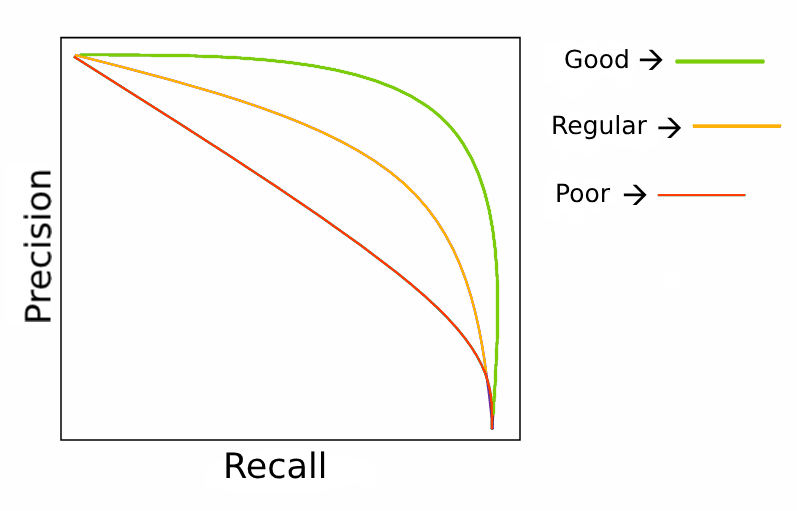

We extract the recall, precision, and score vectors:

[recall,precision,scores] = precisionRecall(metrics);

Now we plot the **precision-recall curve** for a specific class (e.g., the first one):

figure
plot(recall{3},precision{3})
grid on
title("Precision vs Recall");
xlabel("Recall");
ylabel("Precision");

#### Summary

At this point, we've covered the following:

- What IoU (Intersection over Union) is.

- How the confusion matrix works in object detection.

- How to compute **precision**, **recall**, and **F1-score**.

- How to plot precision, recall, and F1-score vs. confidence.

- How to compute and interpret **precision vs. recall curves**.

However, the metrics we’ve computed so far do not fully capture **how well the bounding boxes are located**. For this purpose, a more comprehensive metric is used in object detection.

## Mean Average Precision (mAP)

The **mean Average Precision** (mAP) is one of the most common metric in object detection to summarize both **precision** and **localization quality**.

The **mAP** is calculated as follows:

- Starting from the **confusion matrix**, the precision and recall for the model are calculated for each class.

- By varying the decision threshold, the corresponding **precision-recall curve** is generated for each class, along with its associated** area under the curve **(AUC).The area under each precision-recall curve is known as the **Average Precision** (AP).

- Finally, the **mean Average Precision **(mAP) is computed by averaging the AP values across all classes.

**mAP@50** means AP is computed with an IoU threshold of 0.50.

**mAP@95** refers either to the AP calculated at an IoU threshold of 0.95, or more commonly, to the average AP computed across multiple IoU thresholds from 0.50 to 0.95 in increments of 0.05.

The **range** of mAP is from **0 to 1**:

- **mAP = 1** means the model has perfect precision and localization across all classes.

- **mAP = 0** means the model completely fails to detect objects correctly.

In the following code snippet, we display the Average Precision for each class at an IoU threshold of 0.50:

ap = averagePrecision(metrics);
disp("ap")
disp(ap)
disp("mAP") 
disp(sum(ap)/3)

We can display summary metrics for the entire dataset and for individual classes using:

[summaryDataset,summaryClass] = summarize(metrics);
disp(summaryDataset)
disp(summaryClass)